clear; close all; clc;

# **Fase 1**

**Comum a todos os cenários**

quick = false;         % quando estivcer tudo bom, coloco a false para fazer mais simulações
rng('default');        % repoe o gerador
snr_db = 0:2:40;
if quick, D12 = 50;   D512 = 3;
else,     D12 = 2000; D512 = 200; end
T12 = 50;  T512 = 10;

# Cenários

### Cenário 1 A

16 users × 1 antena

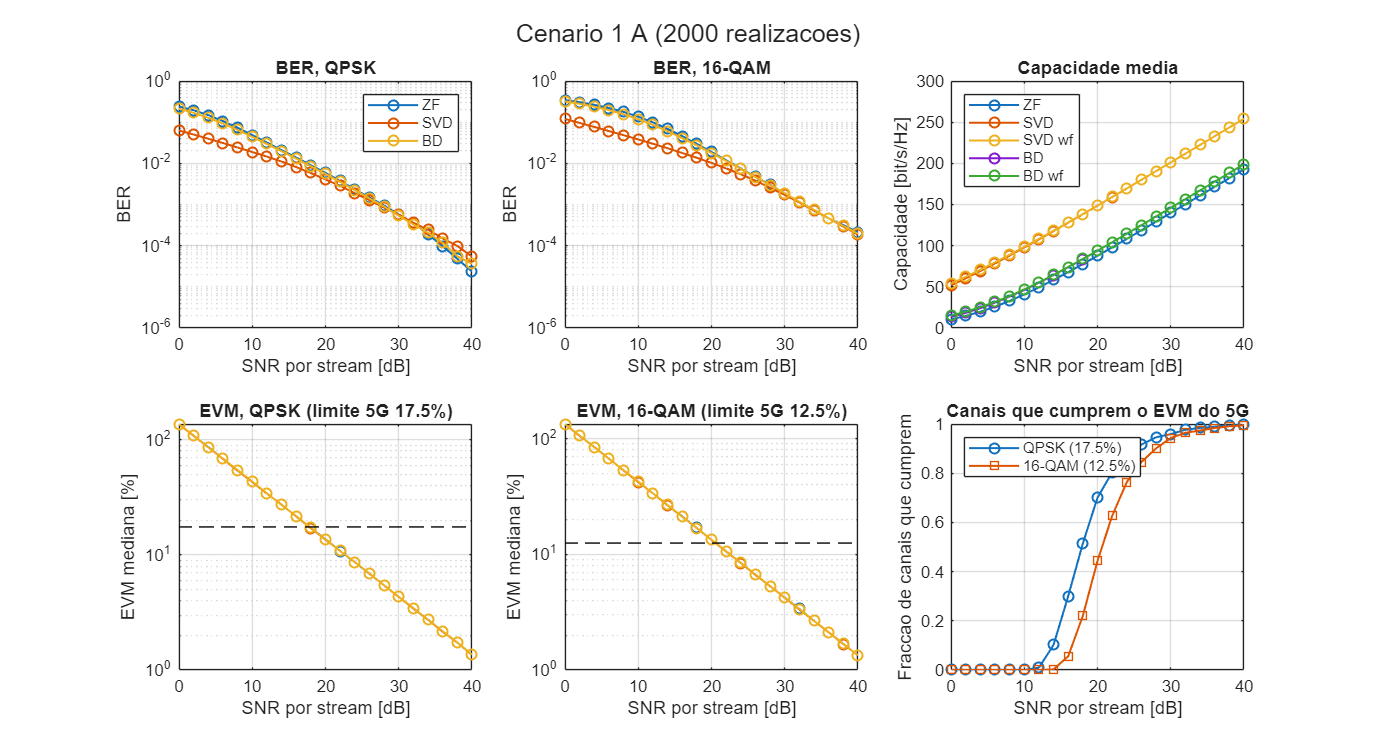

rng(1);
Nt = 16;  sizes = ones(1,16);
R4_1A  = simula_cenario(Nt, sizes, D12, T12, snr_db, 4);
R16_1A = simula_cenario(Nt, sizes, D12, T12, snr_db, 16);
plota_cenario(R4_1A, R16_1A, snr_db, 'Cenario 1 A');

### Cenário 1 B

2 users × 8 antenas

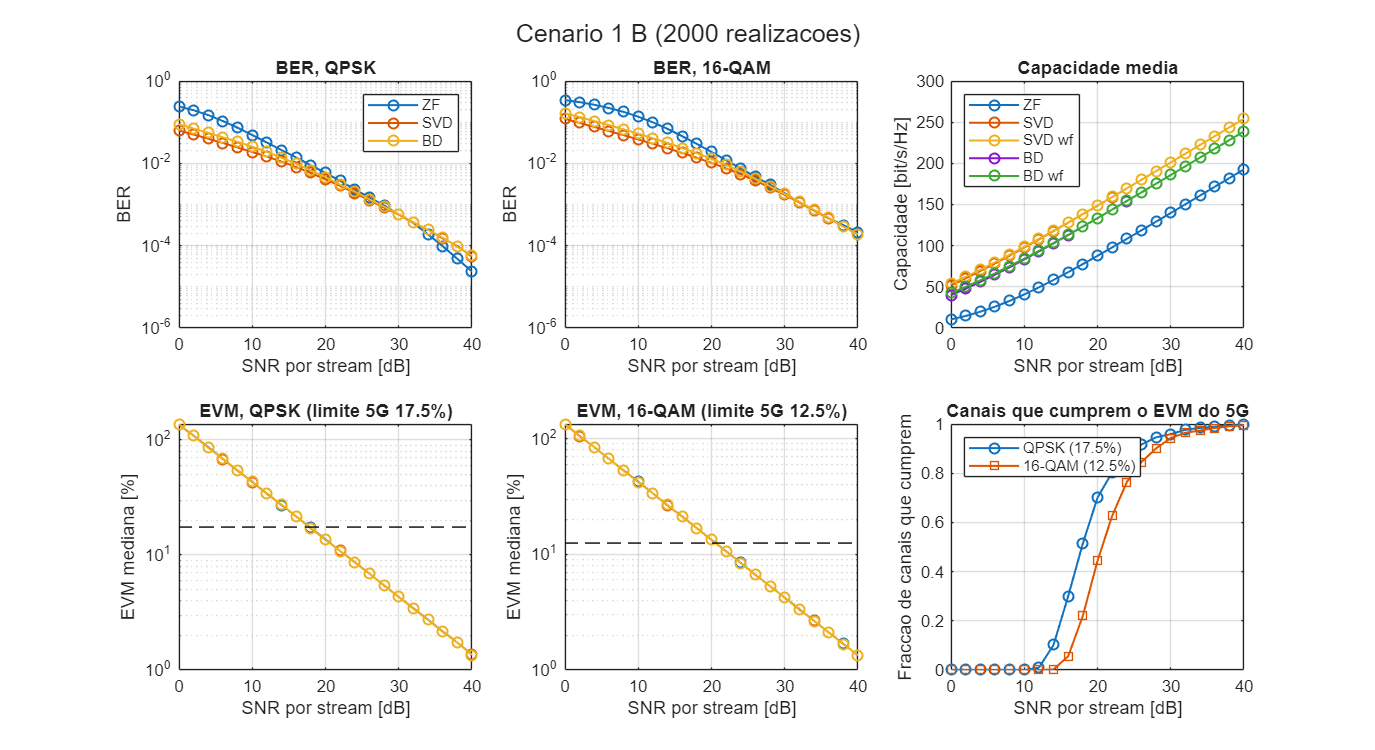

rng(1);
Nt = 16;  sizes = [8 8];
R4_1B  = simula_cenario(Nt, sizes, D12, T12, snr_db, 4);
R16_1B = simula_cenario(Nt, sizes, D12, T12, snr_db, 16);
plota_cenario(R4_1B, R16_1B, snr_db, 'Cenario 1 B');

### Cenário 2 A

512 users × 1 antena

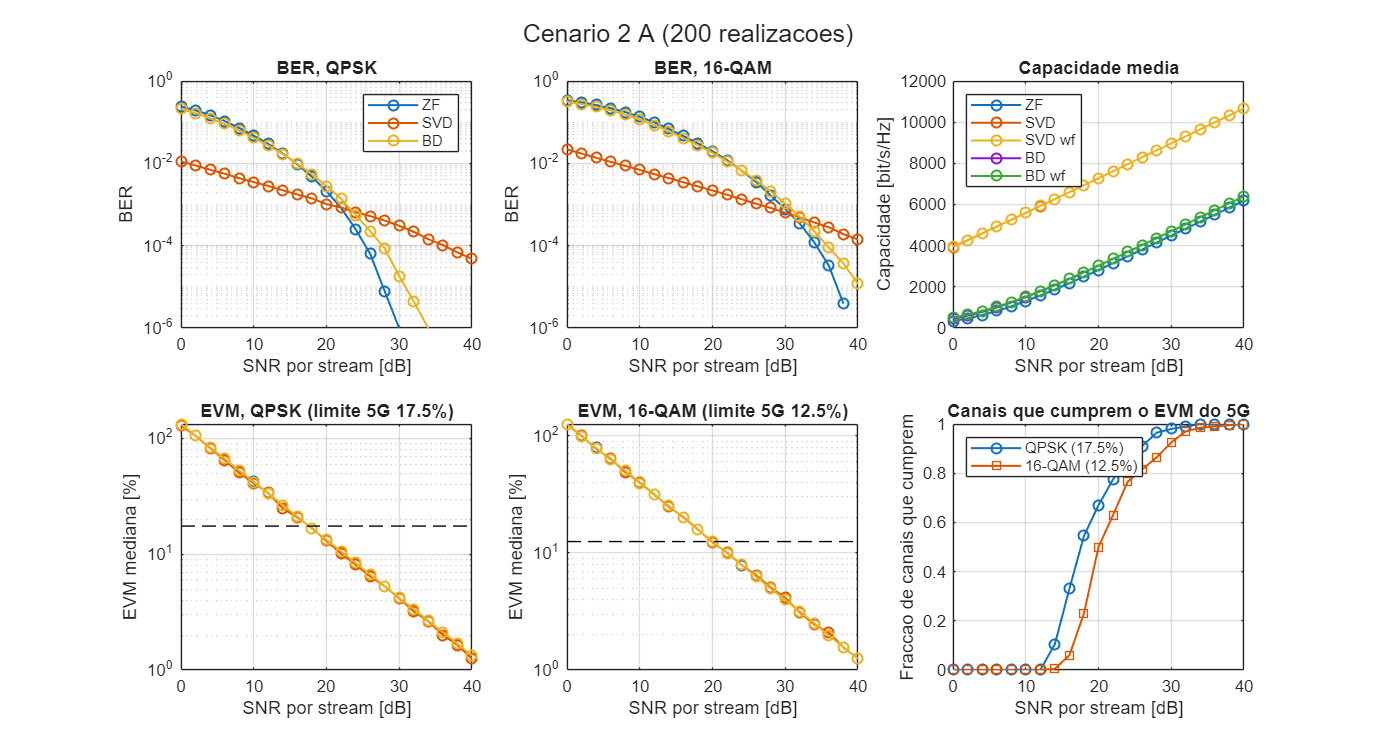

rng(1);
Nt = 512;  sizes = ones(1,512);
R4_2A  = simula_cenario(Nt, sizes, D512, T512, snr_db, 4);
R16_2A = simula_cenario(Nt, sizes, D512, T512, snr_db, 16);
plota_cenario(R4_2A, R16_2A, snr_db, 'Cenario 2 A');

### Cenário 2 B

64 users × 8 antenas    

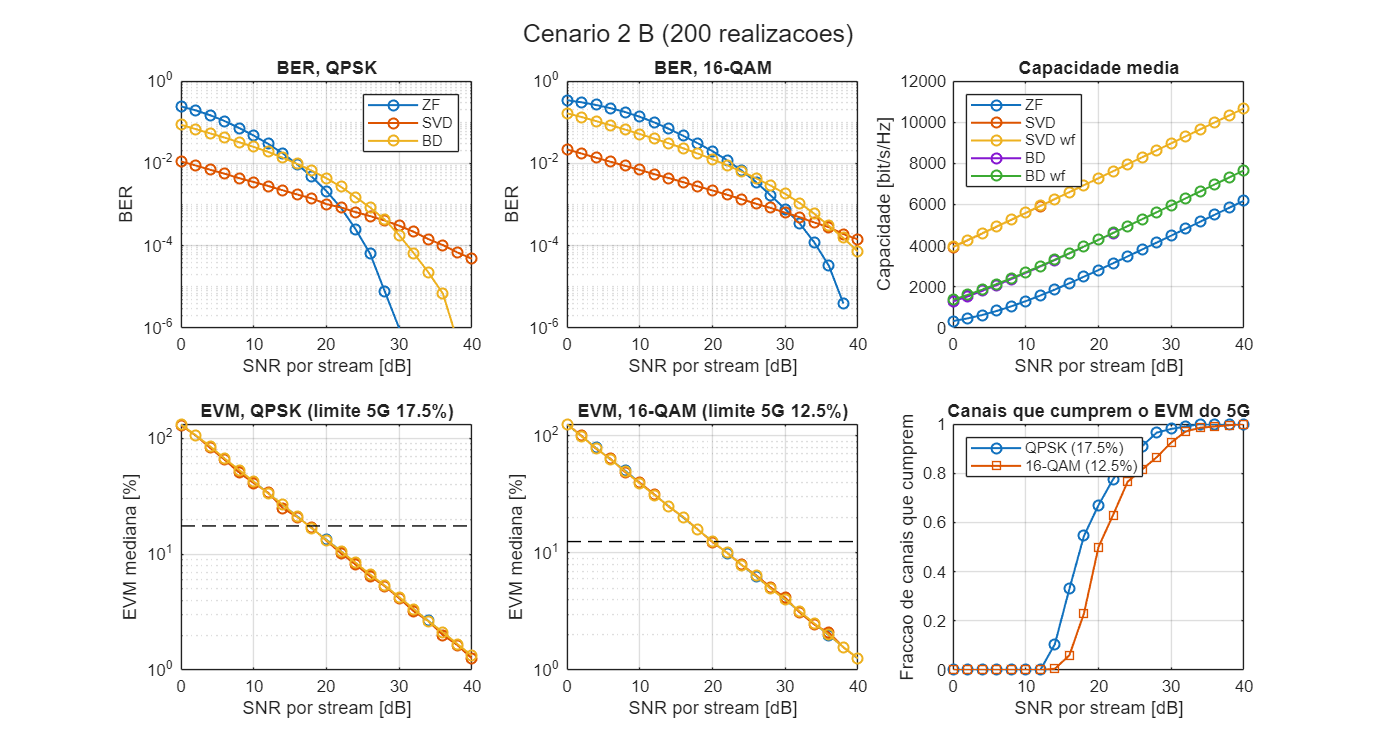

rng(1);
Nt = 512;  sizes = 8*ones(1,64);
R4_2B  = simula_cenario(Nt, sizes, D512, T512, snr_db, 4);
R16_2B = simula_cenario(Nt, sizes, D512, T512, snr_db, 16);
plota_cenario(R4_2B, R16_2B, snr_db, 'Cenario 2 B');

# Capacidades e EVM

Rs   = {R4_1A,  R4_1B,  R4_2A,  R4_2B};      % QPSK
Rs16 = {R16_1A, R16_1B, R16_2A, R16_2B};     % 16-QAM
nomes = {'1A','1B','2A','2B'};

% Capacidade media [bit/s/Hz] para varias SNR por stream
for snr_ref = [10 20 30]
    i = find(snr_db == snr_ref);
    C = zeros(4,5);
    for c = 1:4, C(c,:) = Rs{c}.C(i,:); end
    Tab = array2table(C, 'VariableNames', {'ZF','SVD','SVD_wf','BD','BD_wf'}, 'RowNames', nomes);
    fprintf('\nCapacidade media [bit/s/Hz], SNR = %d dB por stream:\n', snr_ref);
    disp(Tab)
end


Capacidade media [bit/s/Hz], SNR = 10 dB por stream:


            ZF       SVD      SVD_wf      BD      BD_wf 
          ______    ______    ______    ______    ______

    1A    40.772    97.696    98.544    46.343    46.814
    1B    40.772    97.696    98.544    83.228     84.26
    2A    1303.8    5590.9    5596.3    1499.6    1515.5
    2B    1303.8    5590.9    5596.3    2675.6    2708.6




Capacidade media [bit/s/Hz], SNR = 20 dB por stream:


            ZF       SVD      SVD_wf      BD      BD_wf 
          ______    ______    ______    ______    ______

    1A    87.698    148.57    148.75    93.895    93.967
    1B    87.698    148.57    148.75    133.37    133.56
    2A    2815.7    7277.8    7279.5    3031.8      3033
    2B    2815.7    7277.8    7279.5    4281.5    4286.7




Capacidade media [bit/s/Hz], SNR = 30 dB por stream:


            ZF       SVD      SVD_wf      BD      BD_wf 
          ______    ______    ______    ______    ______

    1A    139.71    201.17    201.19       146    146.01
    1B    139.71    201.17    201.19    185.84    185.86
    2A    4489.1    8974.3    8974.8    4706.5    4706.5
    2B    4489.1    8974.3    8974.8    5962.1    5962.3




% SNR minima [dB] a que a mediana do EVM cumpre o limite 5G (resolucao = interpolada entre pontos da grelha)
primeiro = @(m,lim) cruza(snr_db, m, lim);
snr_min = zeros(4,2);
for c = 1:4
    snr_min(c,1) = primeiro(median(Rs{c}.EVM(:,:,1), 1),   17.5);   % QPSK
    snr_min(c,2) = primeiro(median(Rs16{c}.EVM(:,:,1), 1), 12.5);   % 16-QAM
end
fprintf('\nSNR minima por stream [dB] para EVM mediana abaixo do limite 5G:\n');


SNR minima por stream [dB] para EVM mediana abaixo do limite 5G:


disp(array2table(snr_min, 'VariableNames', {'QPSK_17_5', 'QAM16_12_5'}, 'RowNames', nomes))

          QPSK_17_5    QAM16_12_5
          _________    __________

    1A      17.84        20.577  
    1B      17.84        20.577  
    2A     17.573         20.01  
    2B     17.573         20.01  



# Complexidade

nomes = {'1A','1B','2A','2B'};
cfg   = {16, ones(1,16); 16, [8 8]; 512, ones(1,512); 512, 8*ones(1,64)};
nrep  = [200 200 3 3];                 % repeticoes (menos nos cenarios de 512)
t_ms  = zeros(4,4);
for c = 1:4
    t_ms(c,:) = mede_complexidade(cfg{c,1}, cfg{c,2}, nrep(c), true);
end
fprintf('\nTempo por subportadora [ms] (uma matriz H):\n');


Tempo por subportadora [ms] (uma matriz H):


disp(array2table(t_ms, 'VariableNames', {'ZF','SVD','BD_rapida','BD_classica'}, 'RowNames', nomes))

             ZF         SVD       BD_rapida    BD_classica
          ________    ________    _________    ___________

    1A    0.021228    0.031192      0.0996       2.5748   
    1B    0.018924    0.030181    0.042399       1.1993   
    2A      12.726      74.222      26.192        34747   
    2B       14.24      71.843      18.686       4123.6   



Nsc = 512;                             % subportadoras OFDM
fprintf('\nTempo por simbolo OFDM [s] (%d subportadoras):\n', Nsc);


Tempo por simbolo OFDM [s] (512 subportadoras):


disp(array2table(t_ms*Nsc/1e3, 'VariableNames', {'ZF','SVD','BD_rapida','BD_classica'}, 'RowNames', nomes))

             ZF          SVD       BD_rapida    BD_classica
          _________    ________    _________    ___________

    1A     0.010869     0.01597    0.050995        1.3183  
    1B    0.0096891    0.015452    0.021708       0.61404  
    2A       6.5156      38.002       13.41         17790  
    2B       7.2909      36.784      9.5675        2111.3  



# Pré-codificação

### ZF

Calcula W = Hᴴ (H Hᴴ)⁻¹, a matriz que anula a interferência entre streams

function W = zf_precoder(H)
W = H' / (H*H');
end

### SVD

SVD do canal completo: limite superior (receptores a cooperar)

function [W, G, s] = svd_precoder(H)
[U, S, V] = svd(H);
W = V;
G = U';
s = diag(S);
end

### Water-filling

Distribui a potência pelos canais para maximizar a capacidade

function p = water_filling(g, P)
% g: ganhos de potencia dos canais (sigma_i^2); P: potencia total (ruido unitario)
g = g(:);  n = numel(g);
[gs, ordem] = sort(g, 'descend');
inv_g = 1 ./ gs;
mu = (P + cumsum(inv_g)) ./ (1:n)';       % nivel de agua candidato com k canais
k  = find(mu > inv_g, 1, 'last');         % nº de canais activos
p = zeros(n,1);
p(ordem) = max(mu(k) - inv_g, 0);
end

### BD

Block Diagonalization: anula a interferência entre utilizadores, mas deixa a dos streams do mesmo user (que ele resolve com as suas antenas)

function [W, G, e] = bd_precoder(H, sizes, atalho)
% Block Diagonalization: W_j = V0_j * V1_j
%   V0_j : base do espaco nulo dos canais dos outros utilizadores
%   V1_j : SVD do canal efectivo H_j*V0_j
if nargin < 3, atalho = true; end        % atalho = false: BD classico (so para medir complexidade)
[Nrt, Nt] = size(H);
st = [0 cumsum(sizes)];
quadrada = atalho && (Nrt == Nt);
if quadrada, Hi = inv(H); end            % atalho: colunas de inv(H) geram o espaco nulo
W = [];  G = zeros(Nrt, Nrt);  e = [];  r = 0;
for j = 1:numel(sizes)
    a = st(j)+1;  b = st(j+1);
    Hj = H(a:b, :);                       % canal do user j
    if quadrada
        [V0, ~] = qr(Hi(:, a:b), 0);      % Hi(:,a:b) e ortogonal as linhas dos outros users
    else
        Ht = H([1:a-1, b+1:Nrt], :);      % canal dos outros users
        [~, ~, V] = svd(Ht);
        V0 = V(:, min(size(Ht))+1:end);   % espaco nulo de Ht
    end
    [U, S, V1] = svd(Hj*V0, 'econ');      % canal efectivo do user j
    s = diag(S);  L = numel(s);
    W = [W, V0*V1];                       %#ok<AGROW>
    e = [e; s];                           %#ok<AGROW>
    G(r+1:r+L, a:b) = U';
    r = r + L;
end
G = G(1:r, :);
end

### Modulação

function [u, bits] = mod_qam(Ns, T, M)
% Simbolos QAM Gray, potencia media 1 (M = 4: QPSK, M = 16: 16-QAM)
if M == 4
    bits = {randi([0 1],Ns,T), randi([0 1],Ns,T)};            % sinal de I e de Q
    u = ((1-2*bits{1}) + 1j*(1-2*bits{2})) / sqrt(2);
else
    bits = {randi([0 1],Ns,T), randi([0 1],Ns,T), randi([0 1],Ns,T), randi([0 1],Ns,T)};
    u = ((1-2*bits{1}).*(3-2*bits{3}) + 1j*(1-2*bits{2}).*(3-2*bits{4})) / sqrt(10);
end
end

function ne = conta_erros(uh, bits, M)
ne = sum(sum((real(uh) < 0) ~= bits{1})) + sum(sum((imag(uh) < 0) ~= bits{2}));
if M == 16
    ne = ne + sum(sum((abs(real(uh))*sqrt(10) < 2) ~= bits{3})) ...
            + sum(sum((abs(imag(uh))*sqrt(10) < 2) ~= bits{4}));
end
end

function p = ber_teo(g, M)
% BER teorica (AWGN, Gray) para SNR por simbolo g (potencia media 1)
if M == 4
    p = 0.5*erfc(sqrt(g/2));
else
    a = sqrt(g/10);
    p = 3/8*erfc(a) + 1/4*erfc(3*a) - 1/8*erfc(5*a);
end
end

function R = simula_cenario(Nt, sizes, D, T, snr_db, M)
% D realizacoes de canal Rayleigh; devolve BER (sim. e teorica), capacidade e EVM
Nrt = sum(sizes);  Ns = Nrt;  nS = numel(snr_db);
erros = zeros(nS,3);  teo = zeros(nS,3);  cap = zeros(nS,5);
EVMd  = zeros(D,nS,3);                                   % colunas: ZF, SVD, BD
for d = 1:D
    H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    W_zf = zf_precoder(H);
    [W_svd, G_svd, s]  = svd_precoder(H);
    [W_bd, G_bd, e_bd] = bd_precoder(H, sizes);
    [u, bits] = mod_qam(Ns, T, M);
    for i = 1:nS
        snr_i = 10^(snr_db(i)/10);
        n     = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2 = Ns*snr_i / norm(W_zf,'fro')^2;
        Y = cell(1,3);
        Y{1} = (H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2);
        Y{2} = (G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s);
        Y{3} = (G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd);
        for k = 1:3
            erros(i,k)  = erros(i,k) + conta_erros(Y{k}, bits, M);
            EVMd(d,i,k) = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
        end
        teo(i,1) = teo(i,1) + ber_teo(beta2, M);
        teo(i,2) = teo(i,2) + mean(ber_teo(snr_i*s.^2, M));
        teo(i,3) = teo(i,3) + mean(ber_teo(snr_i*e_bd.^2, M));
        p_s = water_filling(s.^2,    Ns*snr_i);
        p_b = water_filling(e_bd.^2, numel(e_bd)*snr_i);
        cap(i,1) = cap(i,1) + Ns*log2(1 + beta2);
        cap(i,2) = cap(i,2) + sum(log2(1 + snr_i*s.^2));
        cap(i,3) = cap(i,3) + sum(log2(1 + p_s.*s.^2));
        cap(i,4) = cap(i,4) + sum(log2(1 + snr_i*e_bd.^2));
        cap(i,5) = cap(i,5) + sum(log2(1 + p_b.*e_bd.^2));
    end
end
R.BER     = erros / (log2(M)*Ns*T*D);
R.BER(R.BER == 0) = NaN;
R.BER_teo = teo / D;
R.C       = cap / D;
R.EVM     = EVMd;
end

function plota_cenario(R4, R16, snr_db, nome)
D = size(R4.EVM, 1);
figure('Name', nome, 'Position', [100 100 1100 600]);
subplot(2,3,1); semilogy(snr_db, R4.BER, 'o-', 'LineWidth', 1.2); grid on; ylim([1e-6 1]); yticks([1e-6 1e-4 1e-2 1]);
legend('ZF','SVD','BD'); xlabel('SNR por stream [dB]'); ylabel('BER'); title('BER, QPSK');
subplot(2,3,2); semilogy(snr_db, R16.BER, 'o-', 'LineWidth', 1.2); grid on; ylim([1e-6 1]); yticks([1e-6 1e-4 1e-2 1]);
xlabel('SNR por stream [dB]'); ylabel('BER'); title('BER, 16-QAM');
subplot(2,3,3); plot(snr_db, R4.C, 'o-', 'LineWidth', 1.2); grid on;
legend('ZF','SVD','SVD wf','BD','BD wf','Location','northwest');
xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]'); title('Capacidade media');
subplot(2,3,4); semilogy(snr_db, squeeze(median(R4.EVM,1)), 'o-', 'LineWidth', 1.2); hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--'); grid on;
xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]'); title('EVM, QPSK (limite 5G 17.5%)');
subplot(2,3,5); semilogy(snr_db, squeeze(median(R16.EVM,1)), 'o-', 'LineWidth', 1.2); hold on;
plot(snr_db, 12.5*ones(size(snr_db)), 'k--'); grid on;
xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]'); title('EVM, 16-QAM (limite 5G 12.5%)');
subplot(2,3,6); plot(snr_db, mean(R4.EVM(:,:,1) < 17.5, 1), 'o-', ...
                     snr_db, mean(R16.EVM(:,:,1) < 12.5, 1), 's-', 'LineWidth', 1.2); grid on;
legend('QPSK (17.5%)','16-QAM (12.5%)','Location','northwest'); xlabel('SNR por stream [dB]');
ylabel('Fraccao de canais que cumprem'); title('Canais que cumprem o EVM do 5G');
if exist('sgtitle', 'file'), sgtitle(sprintf('%s (%d realizacoes)', nome, D)); end
end

function t = mede_complexidade(Nt, sizes, nrep, com_bd_classica)
% Tempo medio [ms] por subportadora (uma matriz H) de cada pre-codificador
Nrt = sum(sizes);
H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
zf_precoder(H); svd_precoder(H); bd_precoder(H, sizes);          % aquecimento
t = nan(1,4);                                                    % ZF | SVD | BD rapida | BD classica
tic; for r = 1:nrep, zf_precoder(H);        end; t(1) = 1e3*toc/nrep;
tic; for r = 1:nrep, svd_precoder(H);       end; t(2) = 1e3*toc/nrep;
tic; for r = 1:nrep, bd_precoder(H, sizes); end; t(3) = 1e3*toc/nrep;
    if com_bd_classica
        tic; bd_precoder(H, sizes, false);      t(4) = 1e3*toc;      % 1 repeticao
    end
end

function s = cruza(snr_db, m, lim)
% SNR a que a mediana do EVM cruza o limite (interpolacao linear em log10(EVM))
i = find(m < lim, 1);
if isempty(i)
    s = NaN;
elseif i == 1
    s = snr_db(1);
else
    x0 = log10(m(i-1));  x1 = log10(m(i));
    s = snr_db(i-1) + (log10(lim) - x0) * (snr_db(i) - snr_db(i-1)) / (x1 - x0);
end
end